# Esercizio 5

This is a 7 dof robot, with a spherical wrist. The objective is to calculatate the position of the joint variables using the inverse kinematics.

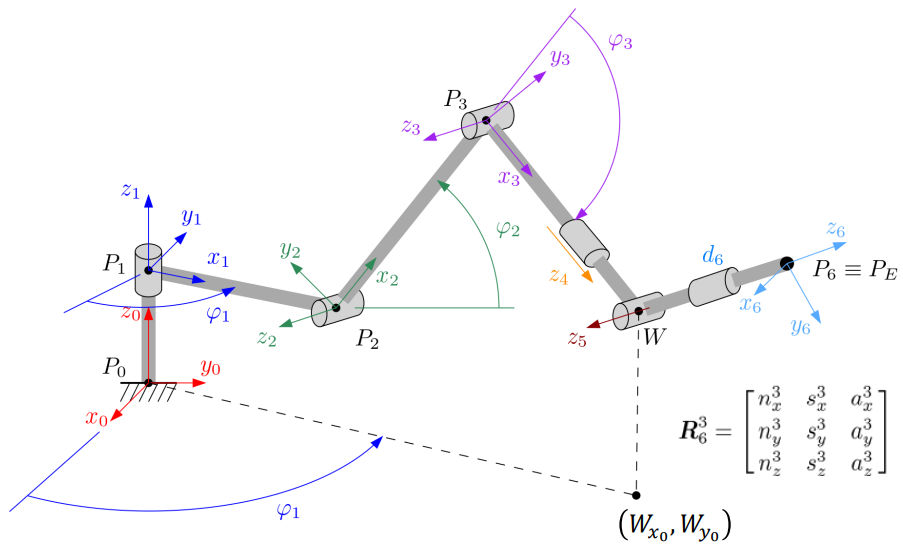

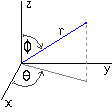The DH table is calculated following this convention:

- $a_i$ = distance along $x_i$ from $O_i$ to the intersection of the $x_i$ and $z_{i-1}$ axes.

- $d_i$ = distance along $z_{i-1}$ from $O_{i-1}$ to the intersection of the $x_i$ and $z_{i-1}$ axes. $d_i$ is variable if joint $i$ is prismatic.

- $\alpha_i$ = the angle between $z_{i-1}$ and $z_i$ measured about $x_i$.

- $\theta_i$ = the angle between $x_{i-1}$ and $x_i$ measured about $z_{i-1}$. $\theta_i$ is variable if joint $i$ is revolute.


$$T_i^{i-1} =

\pmatrix{\cos(\theta_i) & -\sin(\theta_i) & 0 & a_{i-1} \cr \sin(\theta_i)\cos(\alpha_{i-1}) & \cos(\theta_i)\cos(\alpha_{i-1}) & -\sin(\alpha_{i-1}) & -\sin(\alpha_{i-1})d_i \cr \sin(\theta_i)\sin(\alpha_{i-1}) & \cos(\theta_i)\sin(\alpha_{i-1}) & \cos(\alpha_{i-1}) & \cos(\alpha_{i-1})d_i \cr 0 & 0 & 0 & 1}$$


vvajbkfdlwdf

import plotFrame.*;

clear all;
clc;

l01 = 15;
l12 = 10;
l23 = 5;
l3W = 5;
lWE = 5;

PE = [10 10 20]';

theta = pi/4; % angle from horizontal axis
phi = pi/4; % angle from vertical axis

% xproj = lWE*sin(phi)*cos(theta);
% yproj = lWE*sin(phi)*sin(theta);
% zproj = lWE*cos(phi);
% 
% PW = [ PE(1) - xproj;
%        PE(2) - yproj;
%        PE(3) - zproj;
%      ];

R06 = eul2rotm([theta, phi, theta], "ZYZ");

PW = PE - lWE*R06*[0; 0; 1];

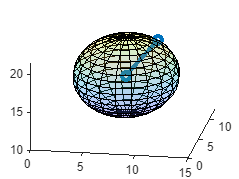

[x, y, z] = sphere;
x = x*lWE;
y = y*lWE;
z = z*lWE;

figure;
hold on;
plot3([PW(1) PE(1)], [PW(2) PE(2)], [PW(3) PE(3)], '-o','LineWidth',3);
sphereSurface = surf(x+PW(1),y+PW(2),z+PW(3));
set(sphereSurface, 'FaceAlpha',0.2);
view([10, 30]);


clear x y z; % just to not keep more variables than needed

fprintf('lWE lenght: %f', norm(PE-PW));

lWE lenght: 5.000000

phi1 = atan2(PW(2), PW(1));

H10 = DHMatrix(0, 0, l01, phi1);
H21 = DHMatrix(l12, pi/2, 0, 0); %% this is just the translation because IDK the phi2 angle right now

newPW = inv(H10*H21)*[PW; 1];
newPW = newPW(1:2);
r = norm(newPW);

c1 = (l23^2 + l3W^2 - r^2)/(2*l23*l3W);
c2 = (r^2 + l23^2 - l3W^2)/(2*l23*r);

gamma = acos(c1);
alpha = acos(c2);

phi3 = pi - gamma;
phi2 = atan2(newPW(2), newPW(1)) - alpha;

rad2deg(phi1)

ans = 45

rad2deg(phi2)

ans = -13.3794

rad2deg(phi3)

ans = 161.7588

H10 = DHMatrix(0, 0, l01, phi1);
H21 = DHMatrix(l12, pi/2, 0, phi2);
H32 = DHMatrix(l23, 0, 0, phi3);

H03 = H10*H21*H32;
R03 = H03(1:3, 1:3);

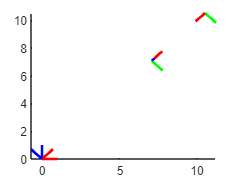

clf;
hold on;

plotFrame(eye(4));
plotFrame(H10);
plotFrame(H10*H21);
plotFrame(H10*H21*H32);

R36 = R03'*R06;

phi4 = atan2(R36(3, 3), R36(2, 3));
phi5 = atan2(norm(R36(2:3, 3)), R36(1, 3));
phi6 = atan2(R36(1,1), -R36(1, 2));

rad2deg(phi4)

ans = 180

rad2deg(phi5)

ans = 103.3794

rad2deg(phi6)

ans = -135

H43 = DHMatrix(l3W, phi4, 0, 0);
H54 = DHMatrix(0, 0, 0, phi5);
H65 = DHMatrix(lWE, phi6, 0, 0);

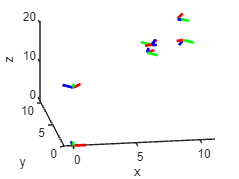

% plotting the reference frames
clf;
hold on;

plotFrame(eye(4));
plotFrame(H10);
plotFrame(H10*H21);
plotFrame(H10*H21*H32);
plotFrame(H10*H21*H32*H43);
plotFrame(H10*H21*H32*H43*H54);
plotFrame(H10*H21*H32*H43*H54*H65);
view([-9 30]);
xlabel('x');
ylabel('y');
zlabel('z');

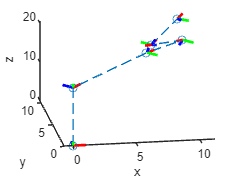

clf;
hold on;

fP0 = [0 0 0 1]';
fP1 = H10*fP0;
fP2 = H10*H21*fP0;
fP3 = H10*H21*H32*fP0;
fP4 = H10*H21*H32*H43*fP0;
fP5 = H10*H21*H32*H43*H54*fP0;
fP6 = H10*H21*H32*H43*H54*H65*fP0;

points = [fP0, fP1, fP2, fP3, fP4, fP5, fP6];

plotFrame(eye(4));
plotFrame(H10);
plotFrame(H10*H21);
plotFrame(H10*H21*H32);
plotFrame(H10*H21*H32*H43);
plotFrame(H10*H21*H32*H43*H54);
plotFrame(H10*H21*H32*H43*H54*H65);
plot3(points(1, :), points(2, :), points(3, :), '--o');
view([-9 30]);
xlabel('x');
ylabel('y');
zlabel('z');

function matrix = DHMatrix(a, alpha, d, theta)
    % function to create the matrix from the DH table row
    matrix = [cos(theta) -sin(theta) 0 a;
              sin(theta)*cos(alpha) cos(theta)*cos(alpha) -sin(alpha) -sin(alpha)*d;
              sin(theta)*sin(alpha) cos(theta)*sin(alpha) cos(alpha) cos(alpha)*d;
              0 0 0 1
             ];
end